# **Práctica 1: Introducción a la Wavelet Toolbox de MATLAB**

## **Ejercicio 1. Generar señales. **

***Crear señales de longitud 2048 que representen cada función en el intervalo [0,1]. Representarlas gráficamente.***

% Generar el intervalo [0,1] de longitud 2048
x = linspace(0,1,2048);

**1) **$f(x)=1$

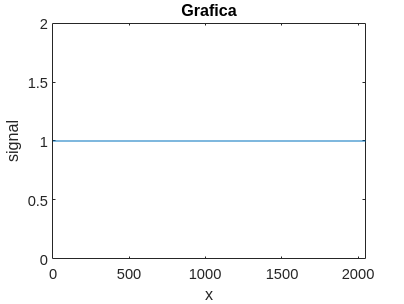

% Crear la señal 
fx1 = ones(size(x));

% Gráficar
plot(fx1)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx1) min(fx1)-1 max(fx1)+1])

**2) **$f(x)=x^2(1-x)$

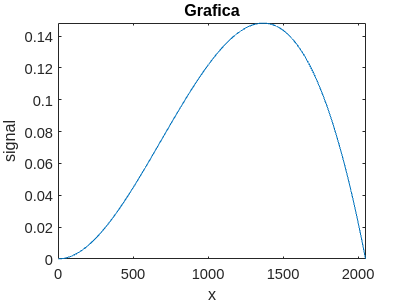

% Crear la señal 
fx2 = x.^2.*(1-x);

% Gráficar
plot(fx2)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx2) min(fx2) max(fx2)])

**3) **$f(x)=x^4(1-x)^6\cos(64\pi x)$

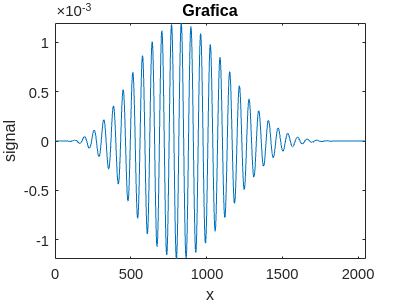

% Crear la señal 
fx3 = x.^4.*(1-x).^6.*cos(64*pi*x);

% Gráficar
plot(fx3)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx3) min(fx3) max(fx3)])

**4) **$f (x) = 1(0,2 < x < 0,3) - 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)$

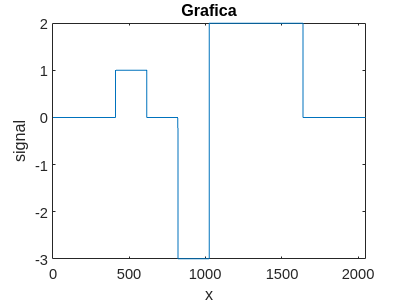

% Crear la señal
fx4 = zeros(size(x));
fx4((0.2 < x) & (x < 0.3)) = 1;
fx4((0.4 < x) & (x < 0.5)) = -3;
fx4((0.5 < x) & (x < 0.8)) = 2;

% Gráficar
plot(fx4)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx4) min(fx4) max(fx4)])

**5) **$f (x) = sign(\sin(12\pi x))$

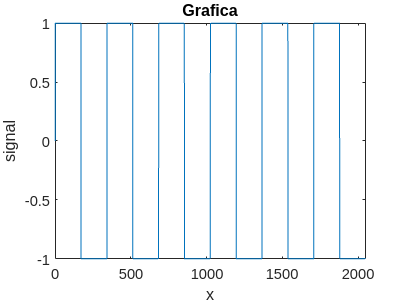

% Crear la señal 
fx5 = sign(sin(12*pi*x));

% Gráficar
plot(fx5)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(fx5) min(fx5) max(fx5)])

## Ejercicio 2. Análisis Wavelet.

**Para cada una de las señales anteriores realizar las siguientes tareas utilizando diferentes wavelets y comparar los resultados.**

- ***Calcular la transformada wavelet de nivel 1. Obtener las subseñales tendencia y fluctuación. Representar gráficamente.***

**1) **$f(x)=1$

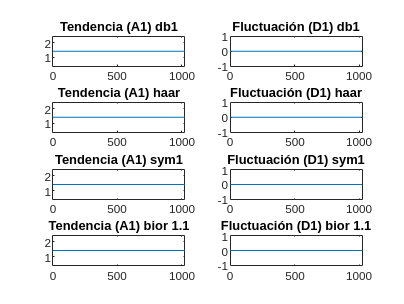

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx1;                                                % Señal
wdb1 = 'db1';                                           % Daubechies
whaar = 'haar';                                         % Haar
wsym1 = 'sym1';                                         % Symlets
wbior1_1 = 'bior1.1';                                   % Biorthogonal


% Transformadas
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                        % Daubechies
[Chaar,Lhaar] = wavedec(s,1,whaar);                     % Haar
[Csym1,Lsym1] = wavedec(s,1,wsym1);                     % Symlets
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb1_A1 = appcoef(Cdb1,Ldb1,wdb1,1);                    % Daubechies
cdb1_D1 = detcoef(Cdb1,Ldb1,1);                         % Daubechies

chaar_A1 = appcoef(Chaar,Lhaar,whaar,1);                % Haar
chaar_D1 = detcoef(Chaar,Lhaar,1);                      % Haar

csym1_A1 = appcoef(Csym1,Lsym1,wsym1,1);                % Symlets
csym1_D1 = detcoef(Csym1,Lsym1,1);                      % Symlets

cbior1_1_A1 = appcoef(Cbior1_1,Lbior1_1,wbior1_1,1);    % Biorthogonal
cbior1_1_D1 = detcoef(Cbior1_1,Lbior1_1,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb1_A1);title('Tendencia (A1) db1')
axis([0 length(cdb1_A1) min(cdb1_A1)-1 max(cdb1_A1)+1]);
subplot(4,2,2)
plot(cdb1_D1);title('Fluctuación (D1) db1')
axis([0 length(cdb1_D1) min(cdb1_D1)-1 max(cdb1_D1)+1]);

% Haar
subplot(4,2,3)
plot(chaar_A1);title('Tendencia (A1) haar')
axis([0 length(chaar_A1) min(chaar_A1)-1 max(chaar_A1)+1]);
subplot(4,2,4)
plot(chaar_D1);title('Fluctuación (D1) haar')
axis([0 length(chaar_D1) min(chaar_D1)-1 max(chaar_D1)+1]);

% Symlets
subplot(4,2,5)
plot(csym1_A1);title('Tendencia (A1) sym1')
axis([0 length(csym1_A1) min(csym1_A1)-1 max(csym1_A1)+1]);
subplot(4,2,6)
plot(csym1_D1);title('Fluctuación (D1) sym1')
axis([0 length(csym1_D1) min(csym1_D1)-1 max(csym1_D1)+1]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_1_A1);title('Tendencia (A1) bior 1.1')
axis([0 length(cbior1_1_A1) min(cbior1_1_A1)-1 max(cbior1_1_A1)+1]);
subplot(4,2,8)
plot(cbior1_1_D1);title('Fluctuación (D1) bior 1.1')
axis([0 length(cbior1_1_D1) min(cbior1_1_D1)-1 max(cbior1_1_D1)+1]);

**2) **$f(x)=x^2(1-x)$

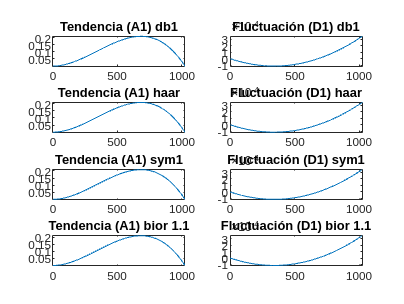

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx2;                                                % Señal
wdb1 = 'db1';                                           % Daubechies
whaar = 'haar';                                         % Haar
wsym1 = 'sym1';                                         % Symlets
wbior1_1 = 'bior1.1';                                   % Biorthogonal


% Transformadas
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                        % Daubechies
[Chaar,Lhaar] = wavedec(s,1,whaar);                     % Haar
[Csym1,Lsym1] = wavedec(s,1,wsym1);                     % Symlets
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb1_A1 = appcoef(Cdb1,Ldb1,wdb1,1);                    % Daubechies
cdb1_D1 = detcoef(Cdb1,Ldb1,1);                         % Daubechies

chaar_A1 = appcoef(Chaar,Lhaar,whaar,1);                % Haar
chaar_D1 = detcoef(Chaar,Lhaar,1);                      % Haar

csym1_A1 = appcoef(Csym1,Lsym1,wsym1,1);                % Symlets
csym1_D1 = detcoef(Csym1,Lsym1,1);                      % Symlets

cbior1_1_A1 = appcoef(Cbior1_1,Lbior1_1,wbior1_1,1);    % Biorthogonal
cbior1_1_D1 = detcoef(Cbior1_1,Lbior1_1,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb1_A1);title('Tendencia (A1) db1')
axis([0 length(cdb1_A1) min(cdb1_A1) max(cdb1_A1)]);
subplot(4,2,2)
plot(cdb1_D1);title('Fluctuación (D1) db1')
axis([0 length(cdb1_D1) min(cdb1_D1) max(cdb1_D1)]);

% Haar
subplot(4,2,3)
plot(chaar_A1);title('Tendencia (A1) haar')
axis([0 length(chaar_A1) min(chaar_A1) max(chaar_A1)]);
subplot(4,2,4)
plot(chaar_D1);title('Fluctuación (D1) haar')
axis([0 length(chaar_D1) min(chaar_D1) max(chaar_D1)]);

% Symlets
subplot(4,2,5)
plot(csym1_A1);title('Tendencia (A1) sym1')
axis([0 length(csym1_A1) min(csym1_A1) max(csym1_A1)]);
subplot(4,2,6)
plot(csym1_D1);title('Fluctuación (D1) sym1')
axis([0 length(csym1_D1) min(csym1_D1) max(csym1_D1)]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_1_A1);title('Tendencia (A1) bior 1.1')
axis([0 length(cbior1_1_A1) min(cbior1_1_A1) max(cbior1_1_A1)]);
subplot(4,2,8)
plot(cbior1_1_D1);title('Fluctuación (D1) bior 1.1')
axis([0 length(cbior1_1_D1) min(cbior1_1_D1) max(cbior1_1_D1)]);

**3) **$f(x)=x^4(1-x)^6\cos(64\pi x)$

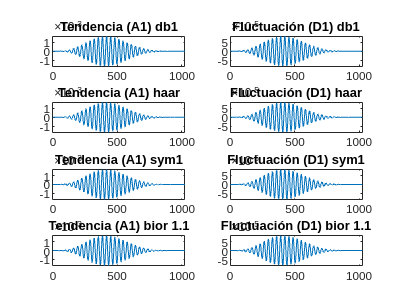

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx3;                                                % Señal
wdb1 = 'db1';                                           % Daubechies
whaar = 'haar';                                         % Haar
wsym1 = 'sym1';                                         % Symlets
wbior1_1 = 'bior1.1';                                   % Biorthogonal


% Transformadas
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                        % Daubechies
[Chaar,Lhaar] = wavedec(s,1,whaar);                     % Haar
[Csym1,Lsym1] = wavedec(s,1,wsym1);                     % Symlets
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb1_A1 = appcoef(Cdb1,Ldb1,wdb1,1);                    % Daubechies
cdb1_D1 = detcoef(Cdb1,Ldb1,1);                         % Daubechies

chaar_A1 = appcoef(Chaar,Lhaar,whaar,1);                % Haar
chaar_D1 = detcoef(Chaar,Lhaar,1);                      % Haar

csym1_A1 = appcoef(Csym1,Lsym1,wsym1,1);                % Symlets
csym1_D1 = detcoef(Csym1,Lsym1,1);                      % Symlets

cbior1_1_A1 = appcoef(Cbior1_1,Lbior1_1,wbior1_1,1);    % Biorthogonal
cbior1_1_D1 = detcoef(Cbior1_1,Lbior1_1,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb1_A1);title('Tendencia (A1) db1')
axis([0 length(cdb1_A1) min(cdb1_A1) max(cdb1_A1)]);
subplot(4,2,2)
plot(cdb1_D1);title('Fluctuación (D1) db1')
axis([0 length(cdb1_D1) min(cdb1_D1) max(cdb1_D1)]);

% Haar
subplot(4,2,3)
plot(chaar_A1);title('Tendencia (A1) haar')
axis([0 length(chaar_A1) min(chaar_A1) max(chaar_A1)]);
subplot(4,2,4)
plot(chaar_D1);title('Fluctuación (D1) haar')
axis([0 length(chaar_D1) min(chaar_D1) max(chaar_D1)]);

% Symlets
subplot(4,2,5)
plot(csym1_A1);title('Tendencia (A1) sym1')
axis([0 length(csym1_A1) min(csym1_A1) max(csym1_A1)]);
subplot(4,2,6)
plot(csym1_D1);title('Fluctuación (D1) sym1')
axis([0 length(csym1_D1) min(csym1_D1) max(csym1_D1)]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_1_A1);title('Tendencia (A1) bior 1.1')
axis([0 length(cbior1_1_A1) min(cbior1_1_A1) max(cbior1_1_A1)]);
subplot(4,2,8)
plot(cbior1_1_D1);title('Fluctuación (D1) bior 1.1')
axis([0 length(cbior1_1_D1) min(cbior1_1_D1) max(cbior1_1_D1)]);

**4) **$f (x) = 1(0,2 < x < 0,3) - 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)$

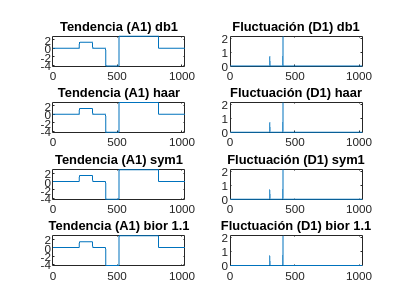

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx4;                                                % Señal
wdb1 = 'db1';                                           % Daubechies
whaar = 'haar';                                         % Haar
wsym1 = 'sym1';                                         % Symlets
wbior1_1 = 'bior1.1';                                   % Biorthogonal


% Transformadas
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                        % Daubechies
[Chaar,Lhaar] = wavedec(s,1,whaar);                     % Haar
[Csym1,Lsym1] = wavedec(s,1,wsym1);                     % Symlets
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb1_A1 = appcoef(Cdb1,Ldb1,wdb1,1);                    % Daubechies
cdb1_D1 = detcoef(Cdb1,Ldb1,1);                         % Daubechies

chaar_A1 = appcoef(Chaar,Lhaar,whaar,1);                % Haar
chaar_D1 = detcoef(Chaar,Lhaar,1);                      % Haar

csym1_A1 = appcoef(Csym1,Lsym1,wsym1,1);                % Symlets
csym1_D1 = detcoef(Csym1,Lsym1,1);                      % Symlets

cbior1_1_A1 = appcoef(Cbior1_1,Lbior1_1,wbior1_1,1);    % Biorthogonal
cbior1_1_D1 = detcoef(Cbior1_1,Lbior1_1,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb1_A1);title('Tendencia (A1) db1')
axis([0 length(cdb1_A1) min(cdb1_A1) max(cdb1_A1)]);
subplot(4,2,2)
plot(cdb1_D1);title('Fluctuación (D1) db1')
axis([0 length(cdb1_D1) min(cdb1_D1) max(cdb1_D1)]);

% Haar
subplot(4,2,3)
plot(chaar_A1);title('Tendencia (A1) haar')
axis([0 length(chaar_A1) min(chaar_A1) max(chaar_A1)]);
subplot(4,2,4)
plot(chaar_D1);title('Fluctuación (D1) haar')
axis([0 length(chaar_D1) min(chaar_D1) max(chaar_D1)]);

% Symlets
subplot(4,2,5)
plot(csym1_A1);title('Tendencia (A1) sym1')
axis([0 length(csym1_A1) min(csym1_A1) max(csym1_A1)]);
subplot(4,2,6)
plot(csym1_D1);title('Fluctuación (D1) sym1')
axis([0 length(csym1_D1) min(csym1_D1) max(csym1_D1)]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_1_A1);title('Tendencia (A1) bior 1.1')
axis([0 length(cbior1_1_A1) min(cbior1_1_A1) max(cbior1_1_A1)]);
subplot(4,2,8)
plot(cbior1_1_D1);title('Fluctuación (D1) bior 1.1')
axis([0 length(cbior1_1_D1) min(cbior1_1_D1) max(cbior1_1_D1)]);

**5) **$f (x) = sign(\sin(12\pi x))$

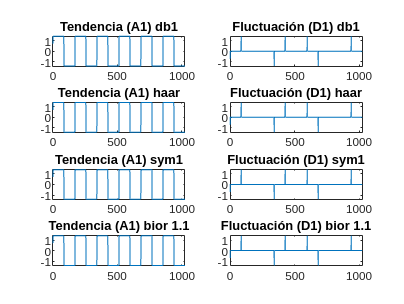

% Calculamos algunas transformadas wavelet

% Nivel 1
s = fx5;                                                % Señal
wdb1 = 'db1';                                           % Daubechies
whaar = 'haar';                                         % Haar
wsym1 = 'sym1';                                         % Symlets
wbior1_1 = 'bior1.1';                                   % Biorthogonal


% Transformadas
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                        % Daubechies
[Chaar,Lhaar] = wavedec(s,1,whaar);                     % Haar
[Csym1,Lsym1] = wavedec(s,1,wsym1);                     % Symlets
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);            % Biorthogonal


% Subseñales de tendencia y fluctiación (coeficientes)
cdb1_A1 = appcoef(Cdb1,Ldb1,wdb1,1);                    % Daubechies
cdb1_D1 = detcoef(Cdb1,Ldb1,1);                         % Daubechies

chaar_A1 = appcoef(Chaar,Lhaar,whaar,1);                % Haar
chaar_D1 = detcoef(Chaar,Lhaar,1);                      % Haar

csym1_A1 = appcoef(Csym1,Lsym1,wsym1,1);                % Symlets
csym1_D1 = detcoef(Csym1,Lsym1,1);                      % Symlets

cbior1_1_A1 = appcoef(Cbior1_1,Lbior1_1,wbior1_1,1);    % Biorthogonal
cbior1_1_D1 = detcoef(Cbior1_1,Lbior1_1,1);             % Biorthogonal


% Plots
figure; 
% Daubechies
subplot(4,2,1)
plot(cdb1_A1);title('Tendencia (A1) db1')
axis([0 length(cdb1_A1) min(cdb1_A1) max(cdb1_A1)]);
subplot(4,2,2)
plot(cdb1_D1);title('Fluctuación (D1) db1')
axis([0 length(cdb1_D1) min(cdb1_D1) max(cdb1_D1)]);

% Haar
subplot(4,2,3)
plot(chaar_A1);title('Tendencia (A1) haar')
axis([0 length(chaar_A1) min(chaar_A1) max(chaar_A1)]);
subplot(4,2,4)
plot(chaar_D1);title('Fluctuación (D1) haar')
axis([0 length(chaar_D1) min(chaar_D1) max(chaar_D1)]);

% Symlets
subplot(4,2,5)
plot(csym1_A1);title('Tendencia (A1) sym1')
axis([0 length(csym1_A1) min(csym1_A1) max(csym1_A1)]);
subplot(4,2,6)
plot(csym1_D1);title('Fluctuación (D1) sym1')
axis([0 length(csym1_D1) min(csym1_D1) max(csym1_D1)]);

% Biorthogonal
subplot(4,2,7)
plot(cbior1_1_A1);title('Tendencia (A1) bior 1.1')
axis([0 length(cbior1_1_A1) min(cbior1_1_A1) max(cbior1_1_A1)]);
subplot(4,2,8)
plot(cbior1_1_D1);title('Fluctuación (D1) bior 1.1')
axis([0 length(cbior1_1_D1) min(cbior1_1_D1) max(cbior1_1_D1)]);

- ***Calcular la energia y representar los perfiles de energia acumulada de la señal original y de la transfomada.***

**1) **$f(x)=1$

% Energia y representaci´on de perfiles de energ´ia acumulada
% de la señal original y de la transformada
%% Funci´on
s = fx1;

% Daubechies
w='db1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0480e+03

[energia_C]=energy(C)         

energia_C = 2.0480e+03

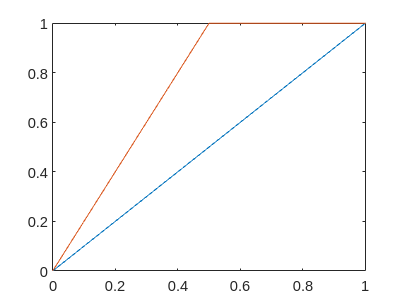

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Haar
w='Haar';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0480e+03

[energia_C]=energy(C)         

energia_C = 2.0480e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Symlets
w='sym1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0480e+03

[energia_C]=energy(C)         

energia_C = 2.0480e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Biorthogonal
w='bior1.1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0480e+03

[energia_C]=energy(C)         

energia_C = 2.0480e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)

**2) **$f(x)=x^2(1-x)$

% Energia y representaci´on de perfiles de energ´ia acumulada
% de la señal original y de la transformada
%% Funci´on
s = fx2;

% Daubechies
w='db1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 19.4952

[energia_C]=energy(C)         

energia_C = 19.4952

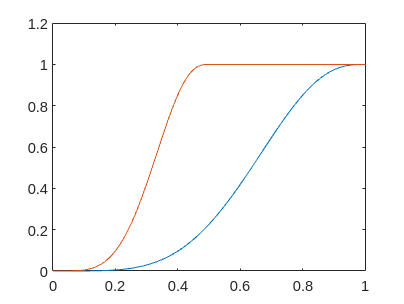

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Coiflets
w='haar';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 19.4952

[energia_C]=energy(C)         

energia_C = 19.4952

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Symlets
w='sym1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 19.4952

[energia_C]=energy(C)         

energia_C = 19.4952

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Biorthogonal
w='bior1.1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 19.4952

[energia_C]=energy(C)         

energia_C = 19.4952

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)

**3) **$f(x)=x^4(1-x)^6\cos(64\pi x)$

% Energia y representaci´on de perfiles de energ´ia acumulada
% de la señal original y de la transformada
%% Funci´on
s = fx3;

% Daubechies
w='db1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 3.8690e-04

[energia_C]=energy(C)         

energia_C = 3.8690e-04

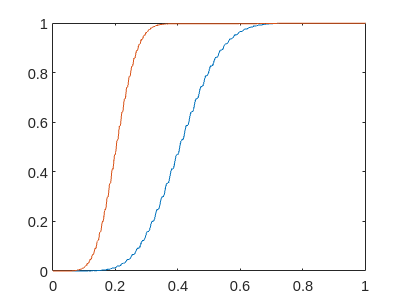

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Coiflets
w='haar';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 3.8690e-04

[energia_C]=energy(C)         

energia_C = 3.8690e-04

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Symlets
w='sym1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 3.8690e-04

[energia_C]=energy(C)         

energia_C = 3.8690e-04

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Biorthogonal
w='bior1.1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 3.8690e-04

[energia_C]=energy(C)         

energia_C = 3.8690e-04

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)

**4) **$f (x) = 1(0,2 < x < 0,3) - 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)$

% Energia y representaci´on de perfiles de energ´ia acumulada
% de la señal original y de la transformada
%% Funci´on
s = fx4;

% Daubechies
w='db1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 4506

[energia_C]=energy(C)         

energia_C = 4.5060e+03

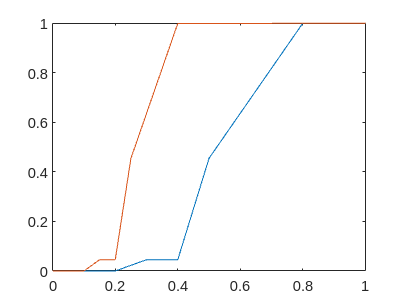

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Coiflets
w='haar';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 4506

[energia_C]=energy(C)         

energia_C = 4.5060e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Symlets
w='sym1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 4506

[energia_C]=energy(C)         

energia_C = 4.5060e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Biorthogonal
w='bior1.1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 4506

[energia_C]=energy(C)         

energia_C = 4.5060e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)

**5) **$f (x) = sign(\sin(12\pi x))$

% Energia y representaci´on de perfiles de energ´ia acumulada
% de la señal original y de la transformada
%% Funci´on
s = fx5;

% Daubechies
w='db1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0470e+03

[energia_C]=energy(C)         

energia_C = 2.0470e+03

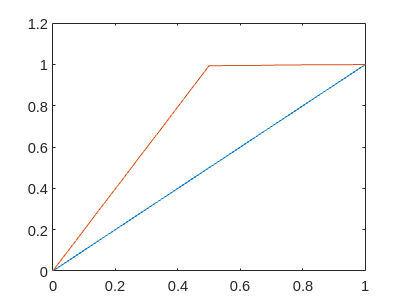

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Coiflets
w='haar';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0470e+03

[energia_C]=energy(C)         

energia_C = 2.0470e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Symlets
w='sym1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0470e+03

[energia_C]=energy(C)         

energia_C = 2.0470e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)


% Biorthogonal
w='bior1.1';
[C,L] = wavedec(s,1,w);
[energia_s]=energy(s)

energia_s = 2.0470e+03

[energia_C]=energy(C)         

energia_C = 2.0470e+03

perfil_energia_s=cumenergy(s);
perfil_energia_transf=cumenergy(C);
figure; plot(x,perfil_energia_s,x,perfil_energia_transf)

- ***En la señal cD1, contar el n´umeros de elementos nulos obtenidos***

% N´umero de valores no nulos Daubechies db1
numeroCeros_cdb1 = nnz(~cdb1_D1)

numeroCeros_cdb1 = 1017


% N´umero de valores no nulos Haar haar
numeroCeros_chaar = nnz(~chaar_D1)

numeroCeros_chaar = 1017


% N´umero de valores no nulos Symlets sym1
numeroCeros_csym1 = nnz(~csym1_D1)

numeroCeros_csym1 = 1017


% N´umero de valores no nulos Biorthogonal cbior1_1
numeroCeros_cbior1_1 = nnz(~cbior1_1_D1)

numeroCeros_cbior1_1 = 1017

- ***Hacer el an*****á*****lisis de multirresolución de la señal: a) obtener las señales de aproximación y detalle A1 y D1; b) reconstruir la señal como s=A1 + D1***

**1) **$f(x)=1$

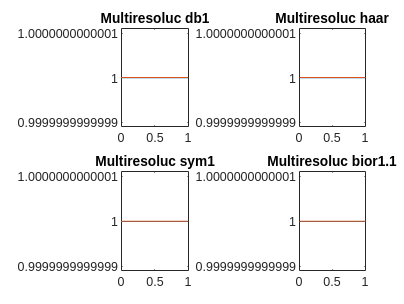

% a) Obtener las señales de aproximación y detalle A1 y D1

% Función
s = fx1;

% Daubechies
wdb1 = 'db1';
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                         
A1_db1 = wrcoef('a',Cdb1,Ldb1,wdb1,1);
D1_db1 = wrcoef('d',Cdb1,Ldb1,wdb1,1);

% Haar
whaar = 'haar';                                      
[Chaar,Lhaar] = wavedec(s,1,whaar);                                    
A1_haar = wrcoef('a',Chaar,Lhaar,whaar,1);
D1_haar = wrcoef('d',Chaar,Lhaar,whaar,1);

% Symlets
wsym1 = 'sym1';                                         
[Csym1,Lsym1] = wavedec(s,1,wsym1);                                        
A1_sym1 = wrcoef('a',Csym1,Lsym1,wsym1,1);
D1_sym1 = wrcoef('d',Csym1,Lsym1,wsym1,1);

% Biorthogonal   
wbior1_1 = 'bior1.1';
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);             
A1_bior1_1 = wrcoef('a',Cbior1_1,Lbior1_1,wbior1_1,1);
D1_bior1_1 = wrcoef('d',Cbior1_1,Lbior1_1,wbior1_1,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db1 = A1_db1 + D1_db1;

% Haar
R_haar = A1_haar + D1_haar;

% Symlets
R_sym1 = A1_sym1 + D1_sym1;

% Biorthogonal 
R_bior1_1 = A1_bior1_1 + D1_bior1_1;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db1); title('Multiresoluc db1')

subplot(2,2,2)
plot(x,s,x,R_haar); title('Multiresoluc haar')

subplot(2,2,3)
plot(x,s,x,R_sym1); title('Multiresoluc sym1')

subplot(2,2,4)
plot(x,s,x,R_bior1_1); title('Multiresoluc bior1.1')

**2) **$f(x)=x^2(1-x)$

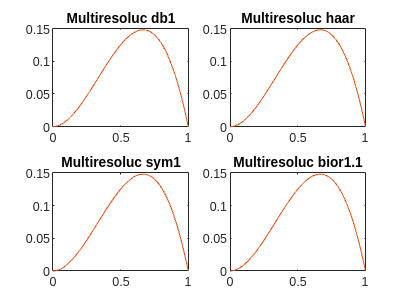

% a) Obtener las señales de aproximación y detalle A1 y D1

% Función
s = fx2;

% Daubechies
wdb1 = 'db1';
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                         
A1_db1 = wrcoef('a',Cdb1,Ldb1,wdb1,1);
D1_db1 = wrcoef('d',Cdb1,Ldb1,wdb1,1);

% Haar
whaar = 'haar';                                      
[Chaar,Lhaar] = wavedec(s,1,whaar);                                    
A1_haar = wrcoef('a',Chaar,Lhaar,whaar,1);
D1_haar = wrcoef('d',Chaar,Lhaar,whaar,1);

% Symlets
wsym1 = 'sym1';                                         
[Csym1,Lsym1] = wavedec(s,1,wsym1);                                        
A1_sym1 = wrcoef('a',Csym1,Lsym1,wsym1,1);
D1_sym1 = wrcoef('d',Csym1,Lsym1,wsym1,1);

% Biorthogonal   
wbior1_1 = 'bior1.1';
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);             
A1_bior1_1 = wrcoef('a',Cbior1_1,Lbior1_1,wbior1_1,1);
D1_bior1_1 = wrcoef('d',Cbior1_1,Lbior1_1,wbior1_1,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db1 = A1_db1 + D1_db1;

% Haar
R_haar = A1_haar + D1_haar;

% Symlets
R_sym1 = A1_sym1 + D1_sym1;

% Biorthogonal 
R_bior1_1 = A1_bior1_1 + D1_bior1_1;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db1); title('Multiresoluc db1')

subplot(2,2,2)
plot(x,s,x,R_haar); title('Multiresoluc haar')

subplot(2,2,3)
plot(x,s,x,R_sym1); title('Multiresoluc sym1')

subplot(2,2,4)
plot(x,s,x,R_bior1_1); title('Multiresoluc bior1.1')

**3) **$f(x)=x^4(1-x)^6\cos(64\pi x)$

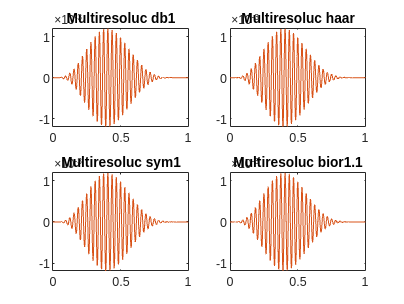

% a) Obtener las señales de aproximación y detalle A1 y D1

% Función
s = fx3;

% Daubechies
wdb1 = 'db1';
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                         
A1_db1 = wrcoef('a',Cdb1,Ldb1,wdb1,1);
D1_db1 = wrcoef('d',Cdb1,Ldb1,wdb1,1);

% Haar
whaar = 'haar';                                      
[Chaar,Lhaar] = wavedec(s,1,whaar);                                    
A1_haar = wrcoef('a',Chaar,Lhaar,whaar,1);
D1_haar = wrcoef('d',Chaar,Lhaar,whaar,1);

% Symlets
wsym1 = 'sym1';                                         
[Csym1,Lsym1] = wavedec(s,1,wsym1);                                        
A1_sym1 = wrcoef('a',Csym1,Lsym1,wsym1,1);
D1_sym1 = wrcoef('d',Csym1,Lsym1,wsym1,1);

% Biorthogonal   
wbior1_1 = 'bior1.1';
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);             
A1_bior1_1 = wrcoef('a',Cbior1_1,Lbior1_1,wbior1_1,1);
D1_bior1_1 = wrcoef('d',Cbior1_1,Lbior1_1,wbior1_1,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db1 = A1_db1 + D1_db1;

% Haar
R_haar = A1_haar + D1_haar;

% Symlets
R_sym1 = A1_sym1 + D1_sym1;

% Biorthogonal 
R_bior1_1 = A1_bior1_1 + D1_bior1_1;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db1); title('Multiresoluc db1')

subplot(2,2,2)
plot(x,s,x,R_haar); title('Multiresoluc haar')

subplot(2,2,3)
plot(x,s,x,R_sym1); title('Multiresoluc sym1')

subplot(2,2,4)
plot(x,s,x,R_bior1_1); title('Multiresoluc bior1.1')

**4) **$f (x) = 1(0,2 < x < 0,3) - 3(0,4 < x < 0,5) + 2(0,5 < x < 0,8)$

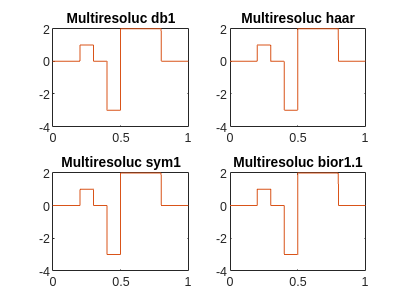

% a) Obtener las señales de aproximación y detalle A1 y D1

% Functción
s = fx4;

% Daubechies
wdb1 = 'db1';
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                         
A1_db1 = wrcoef('a',Cdb1,Ldb1,wdb1,1);
D1_db1 = wrcoef('d',Cdb1,Ldb1,wdb1,1);

% Haar
whaar = 'haar';                                      
[Chaar,Lhaar] = wavedec(s,1,whaar);                                    
A1_haar = wrcoef('a',Chaar,Lhaar,whaar,1);
D1_haar = wrcoef('d',Chaar,Lhaar,whaar,1);

% Symlets
wsym1 = 'sym1';                                         
[Csym1,Lsym1] = wavedec(s,1,wsym1);                                        
A1_sym1 = wrcoef('a',Csym1,Lsym1,wsym1,1);
D1_sym1 = wrcoef('d',Csym1,Lsym1,wsym1,1);

% Biorthogonal   
wbior1_1 = 'bior1.1';
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);             
A1_bior1_1 = wrcoef('a',Cbior1_1,Lbior1_1,wbior1_1,1);
D1_bior1_1 = wrcoef('d',Cbior1_1,Lbior1_1,wbior1_1,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db1 = A1_db1 + D1_db1;

% Haar
R_haar = A1_haar + D1_haar;

% Symlets
R_sym1 = A1_sym1 + D1_sym1;

% Biorthogonal 
R_bior1_1 = A1_bior1_1 + D1_bior1_1;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db1); title('Multiresoluc db1')

subplot(2,2,2)
plot(x,s,x,R_haar); title('Multiresoluc haar')

subplot(2,2,3)
plot(x,s,x,R_sym1); title('Multiresoluc sym1')

subplot(2,2,4)
plot(x,s,x,R_bior1_1); title('Multiresoluc bior1.1')

**5) **$f (x) = sign(\sin(12\pi x))$

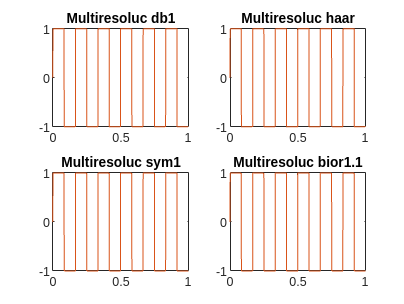

% a) Obtener las señales de aproximación y detalle A1 y D1

% Functción
s = fx5;

% Daubechies
wdb1 = 'db1';
[Cdb1,Ldb1] = wavedec(s,1,wdb1);                         
A1_db1 = wrcoef('a',Cdb1,Ldb1,wdb1,1);
D1_db1 = wrcoef('d',Cdb1,Ldb1,wdb1,1);

% Haar
whaar = 'haar';                                      
[Chaar,Lhaar] = wavedec(s,1,whaar);                                    
A1_haar = wrcoef('a',Chaar,Lhaar,whaar,1);
D1_haar = wrcoef('d',Chaar,Lhaar,whaar,1);

% Symlets
wsym1 = 'sym1';                                         
[Csym1,Lsym1] = wavedec(s,1,wsym1);                                        
A1_sym1 = wrcoef('a',Csym1,Lsym1,wsym1,1);
D1_sym1 = wrcoef('d',Csym1,Lsym1,wsym1,1);

% Biorthogonal   
wbior1_1 = 'bior1.1';
[Cbior1_1,Lbior1_1] = wavedec(s,1,wbior1_1);             
A1_bior1_1 = wrcoef('a',Cbior1_1,Lbior1_1,wbior1_1,1);
D1_bior1_1 = wrcoef('d',Cbior1_1,Lbior1_1,wbior1_1,1);



% b) Reconstruir la señal como s=A1 + D1

% Daubechies
R_db1 = A1_db1 + D1_db1;

% Haar
R_haar = A1_haar + D1_haar;

% Symlets
R_sym1 = A1_sym1 + D1_sym1;

% Biorthogonal 
R_bior1_1 = A1_bior1_1 + D1_bior1_1;


% PLOTS
figure; 
subplot(2,2,1)
plot(x,s,x,R_db1); title('Multiresoluc db1')

subplot(2,2,2)
plot(x,s,x,R_haar); title('Multiresoluc haar')

subplot(2,2,3)
plot(x,s,x,R_sym1); title('Multiresoluc sym1')

subplot(2,2,4)
plot(x,s,x,R_bior1_1); title('Multiresoluc bior1.1')

- ***Reconstruir la señal original con la transformada wavelet inversa. Comparar gráficamente las dos formas de reconstrucción.***

%RECONSTRUCCION:

A1=wrcoef('a',C,L,w,1);
D1=wrcoef('d',C,L,w,1);

figure;
subplot(1,2,1) 
plot(A1); title('Aproximacion');
axis([0 length(A1) min(A1) max(A1)]);
subplot(1,2,2)
plot(D1); title('Detalle')
axis([0 length(A1) min(A1) max(A1)]);
%axis([0 length(D1) -0.01 0.01];

## ***FUNCIONES***

function [y] = energy(x)
%ENERGY Computes the energy of a signal.
%  y = ENERGY(x) returns the energy of x.
%  The energy computed as the sum of the 
%  square of the elements of x.

%   See also CUMENERGY.

y = norm(x)^2;
end
function [y] = cumenergy(x)
%CUMENERGY Computes the normalized cumulative energy profile.
%  y = CUMENERGY(x) creates a vector y with the normalized
%  cumulative energy profile of vector x.

%   See also ENERGY.

y = cumsum(x.^2)/(norm(x)^2);
end